[ Source Code & Plot ]

(1) ~ (4) 

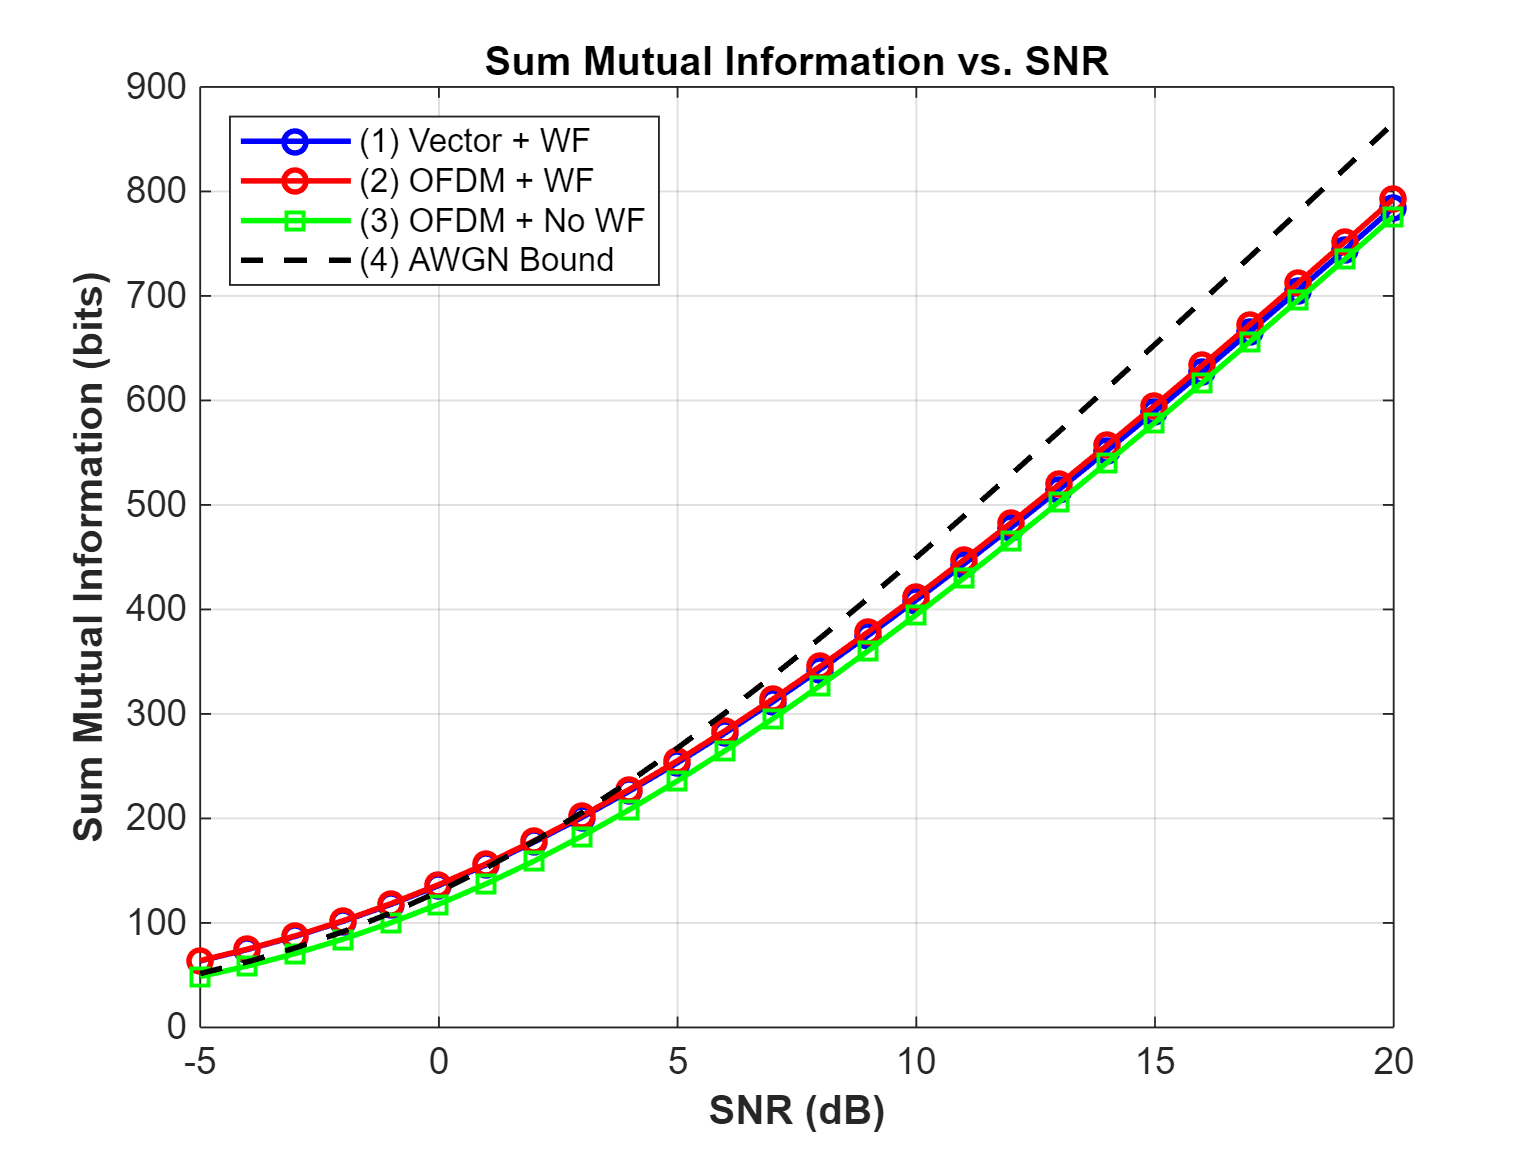

clear; clc; close all;

%% Parameters
K = 128;
L = 2;
total_len = K + L;
h = [0.16 + 0.26i, 0.55 + 0.09i, -0.67 - 0.39i];
h_rev = fliplr(h);

%% Toeplitz matrix (Vector Coding)
H_vec = zeros(K, K + L);
for n = 1:K
    for l = 0:L
        col = n + l;
        if col <= K + L
            H_vec(n, col) = h_rev(l + 1);
        end
    end
end
lambda_vec = svd(H_vec).^2;

%% Circular Toeplitz matrix (OFDM)
h_circ_row = [h_rev, zeros(1, total_len - length(h))];
H_circ = zeros(total_len, total_len);
for row = 1:total_len
    H_circ(row, :) = circshift(h_circ_row, [0, row - 1]);
end
lambda_ofdm = svd(H_circ).^2;

%% OFDM No-WF (via DFT)
h_zp = [h, zeros(1, K - length(h))];
H_k = fft(h_zp);  % K-point DFT
H_gain = abs(H_k).^2;

%% SNR Range
snr_dB = -5:1:20;
SNR_linear = 10.^(snr_dB/10);
sum_mi_vec = zeros(size(snr_dB));
sum_mi_ofdm = zeros(size(snr_dB));
sum_mi_eq = zeros(size(snr_dB));
se_vec = zeros(size(snr_dB));
se_ofdm = zeros(size(snr_dB));
se_eq = zeros(size(snr_dB));
awgn_cap = log2(1 + SNR_linear);  % AWGN Capacity

%% Loop
for idx = 1:length(snr_dB)
    SNR = SNR_linear(idx);

    % --- (1) Vector Coding + WF ---
    inv_gain = 1 ./ (SNR * lambda_vec);
    [inv_sorted, sort_idx] = sort(inv_gain);
    for m = K:-1:1
        inv_eta = (total_len + sum(inv_sorted(1:m))) / m;
        P_temp = inv_eta - inv_sorted(1:m);
        if all(P_temp >= 0)
            break;
        end
    end
    P_vec = zeros(K, 1);
    P_vec(sort_idx(1:m)) = P_temp;
    sum_mi_vec(idx) = sum(log2(1 + SNR * lambda_vec .* P_vec));
    se_vec(idx) = sum_mi_vec(idx) / total_len;

    % --- (2) OFDM + WF ---
    inv_gain = 1 ./ (SNR * lambda_ofdm);
    [inv_sorted, sort_idx] = sort(inv_gain);
    for m = total_len:-1:1
        inv_eta = (total_len + sum(inv_sorted(1:m))) / m;
        P_temp = inv_eta - inv_sorted(1:m);
        if all(P_temp >= 0)
            break;
        end
    end
    P_ofdm = zeros(total_len, 1);
    P_ofdm(sort_idx(1:m)) = P_temp;
    sum_mi_ofdm(idx) = sum(log2(1 + SNR * lambda_ofdm .* P_ofdm));
    se_ofdm(idx) = sum_mi_ofdm(idx) / total_len;

    % --- (3) OFDM + No WF (Equal Power) ---
    sum_mi_eq(idx) = sum(log2(1 + SNR * H_gain));
    se_eq(idx) = sum_mi_eq(idx) / total_len;
end

%% Plot: Sum Mutual Information
figure;
plot(snr_dB, sum_mi_vec, '-bo', 'LineWidth', 1.5); hold on;
plot(snr_dB, sum_mi_ofdm, '-ro', 'LineWidth', 1.5);
plot(snr_dB, sum_mi_eq, '-gs', 'LineWidth', 1.5);
plot(snr_dB, total_len * awgn_cap, 'k--', 'LineWidth', 1.5);
xlabel('SNR (dB)', 'FontWeight','bold');
ylabel('Sum Mutual Information (bits)', 'FontWeight','bold');
legend('(1) Vector + WF', '(2) OFDM + WF', '(3) OFDM + No WF', '(4) AWGN Bound', 'Location', 'NorthWest');
title('Sum Mutual Information vs. SNR', 'FontWeight','bold');
grid on;

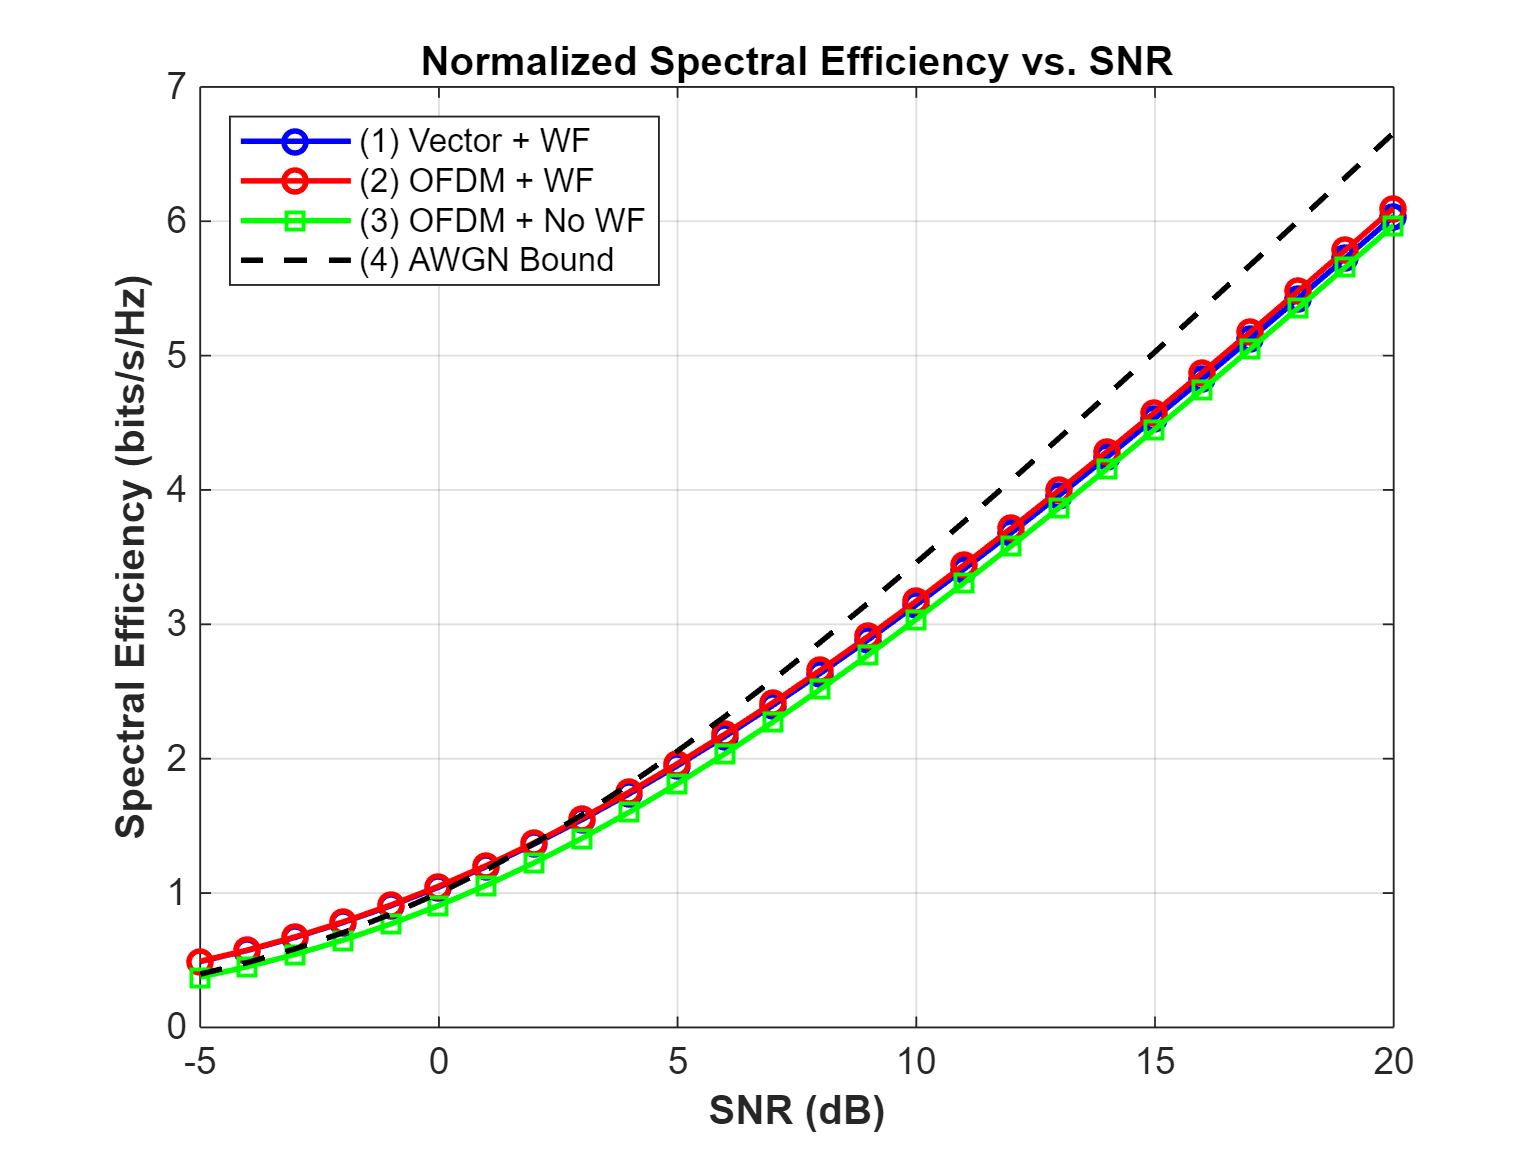


%% Plot: Normalized Spectral Efficiency
figure;
plot(snr_dB, se_vec, '-bo', 'LineWidth', 1.5); hold on;
plot(snr_dB, se_ofdm, '-ro', 'LineWidth', 1.5);
plot(snr_dB, se_eq, '-gs', 'LineWidth', 1.5);
plot(snr_dB, awgn_cap, 'k--', 'LineWidth', 1.5);
xlabel('SNR (dB)', 'FontWeight','bold');
ylabel('Spectral Efficiency (bits/s/Hz)', 'FontWeight','bold');
legend('(1) Vector + WF', '(2) OFDM + WF', '(3) OFDM + No WF', '(4) AWGN Bound', 'Location', 'NorthWest');
title('Normalized Spectral Efficiency vs. SNR', 'FontWeight','bold');
grid on;